clear; close all; clc;

numObs = 2;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = 'observations';

numAct = 1;
actInfo = rlNumericSpec([numAct 1]);
actInfo.LowerLimit = -2;
actInfo.UpperLimit =  2;
actInfo.Name = 'actions';

mdl = 'mass_model';
blk = [mdl,'/RL Agent'];
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);
open_system(mdl)

% Observation path
hiddenlayer = 50;
obsPath = [
    featureInputLayer(prod(obsInfo.Dimension),Name="obsPathIn")
    fullyConnectedLayer(hiddenlayer,Name="obsPathOut")
    ];

% Action path
actPath = [
    featureInputLayer(prod(actInfo.Dimension),Name="actPathIn")
    fullyConnectedLayer(hiddenlayer,Name="actPathOut")
    ];

% Common path
commonPath = [
    additionLayer(2,Name="add") %2つの入力があると設定(in1とin2)
    reluLayer
    fullyConnectedLayer(1)
    ];

% Add layers to layergraph object
criticNet = layerGraph; %層グラフの箱を作成
criticNet = addLayers(criticNet,obsPath);
criticNet = addLayers(criticNet,actPath);
criticNet = addLayers(criticNet,commonPath);

% Connect layers
criticNet = connectLayers(criticNet,"obsPathOut","add/in1");
criticNet = connectLayers(criticNet,"actPathOut","add/in2");

criticNet1 = dlnetwork(criticNet);
criticNet2 = dlnetwork(criticNet);

summary(criticNet1)

   初期化済み: true

   学習可能なパラメーターの数: 301

   入力:
      1   'obsPathIn'   2 の特徴
      2   'actPathIn'   1 の特徴



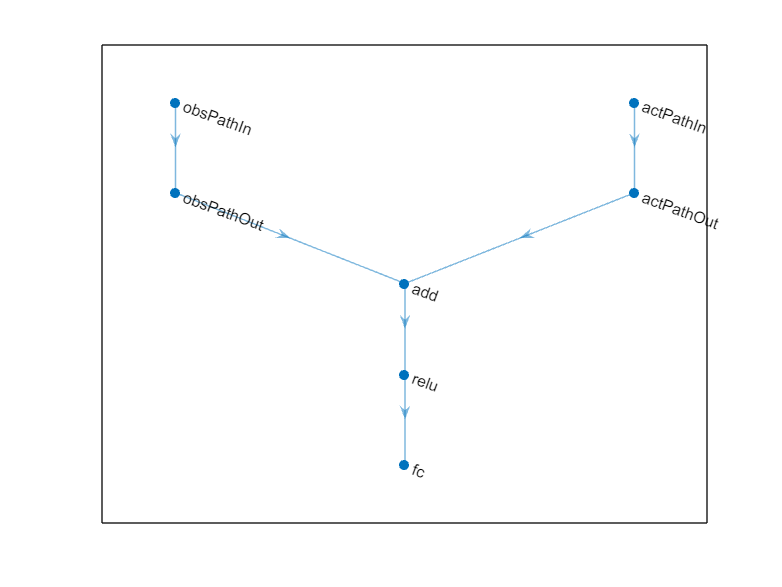


figure()
plot(layerGraph(criticNet1))


critic1 = rlQValueFunction(criticNet1,obsInfo,actInfo); 
critic2 = rlQValueFunction(criticNet2,obsInfo,actInfo);

actorNet = [
    featureInputLayer(prod(obsInfo.Dimension))
    fullyConnectedLayer(hiddenlayer)
    reluLayer
    fullyConnectedLayer(prod(actInfo.Dimension)) 
    tanhLayer('Name','tanh1')
    scalingLayer(Scale = actInfo.UpperLimit)
];

actorNet = dlnetwork(actorNet);
summary(actorNet)

   初期化済み: true

   学習可能なパラメーターの数: 201

   入力:
      1   'input'   2 の特徴



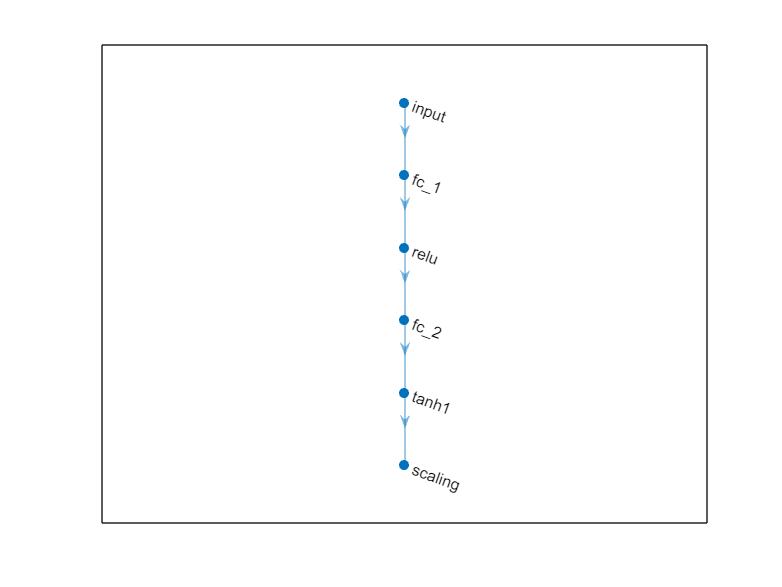

figure
plot(layerGraph(actorNet))


actor  = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo);

criticOptions = rlOptimizerOptions( ...
    "LearnRate",1e-1,... %学習が遅いなら学習率を大きくする(ただし安定しない)
    "Algorithm","adam",...
    "GradientThreshold",1);

actorOptions = rlOptimizerOptions(...
     "LearnRate",1e-1,...
     "GradientThreshold",1);

sampleTime = 0.4;

agentOptions = rlTD3AgentOptions;
agentOptions.DiscountFactor = 0.99;
agentOptions.SampleTime = sampleTime;
agentOptions.CriticOptimizerOptions = criticOptions;
agentOptions.ActorOptimizerOptions = actorOptions;

agent = rlTD3Agent(actor,[critic1 critic2],agentOptions);

maxepisodes = 5000;
maxsteps = 400;
trainingOpts = rlTrainingOptions(...
    'MaxEpisodes',maxepisodes,...
    'MaxStepsPerEpisode',maxsteps,...
    'Verbose',false,...
    'Plots','training-progress',...
    'SaveAgentCriteria','EpisodeReward',...
    'SaveAgentValue',5,...
    'SaveAgentDirectory','savedAgents',...
    'StopTrainingCriteria','EpisodeReward',...
    'StopTrainingValue',0.1);

trainingStats = train(agent,env,trainingOpts);